clear; close all; clc;

## sample data

h = 1.0;
tSpan = 600;
Num = tSpan / h;
to_deg = 180.0/pi;

## save data

t_data = zeros(Num, 1);
x1_data = zeros(Num, 6);
x2_data = x1_data;

## vessel 1

x1 = zeros(6, 1);


## vessel2

x2 = zeros(6, 1);


## input

tau = [
    1.0e5;
    3.0e5;
    5.0e7;
    ];

## RK

for i = 1:Num
    % model 1
    k11 = shipPlant1(x1, tau);
    k12 = shipPlant1(x1+0.5*h*k11, tau);
    k13 = shipPlant1(x1+0.5*h*k12, tau);
    k14 = shipPlant1(x1+h*k13, tau);
    
    x1 = x1 + h * (k11 + 2*k12 + 2*k13 + k14) / 6;
    % limit psi
    x1(3) = rad_round(x1(3));
    
    % model 2
    k11 = shipPlant2(x2, tau);
    k12 = shipPlant2(x2+0.5*h*k11, tau);
    k13 = shipPlant2(x2+0.5*h*k12, tau);
    k14 = shipPlant2(x2+h*k13, tau);
    
    x2 = x2 + h * (k11 + 2*k12 + 2*k13 + k14) / 6;
    % limit psi
    x2(3) = rad_round(x2(3));
    % save
    t_data(i) = i * h;
    x1_data(i, :) = x1';
    x2_data(i, :) = x2';
end

## plot curves

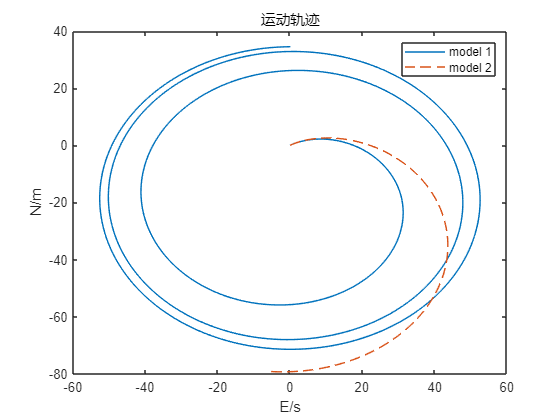

figure
plot(x1_data(:, 2), x1_data(:, 1), x2_data(:, 2), x2_data(:, 1), '--');
title("运动轨迹");xlabel("E/s");ylabel("N/m")
legend("model 1", "model 2");

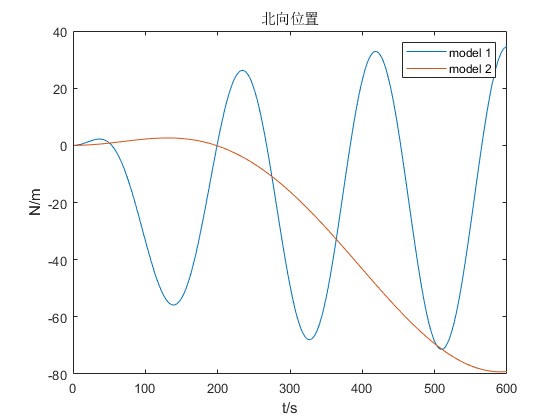


figure
plot(t_data, x1_data(:, 1), t_data, x2_data(:, 1));
title("北向位置");xlabel("t/s");ylabel("N/m")
legend("model 1", "model 2");

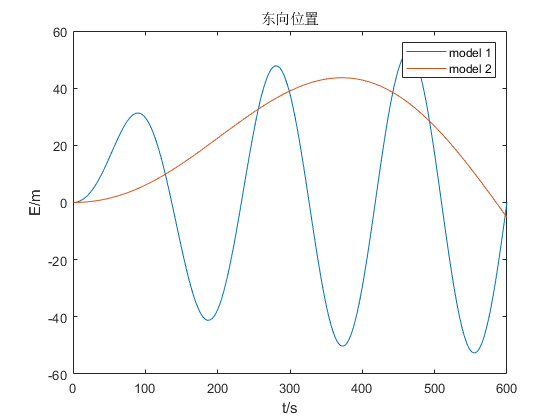


figure
plot(t_data, x1_data(:, 2), t_data, x2_data(:, 2));
title("东向位置");xlabel("t/s");ylabel("E/m")
legend("model 1", "model 2");

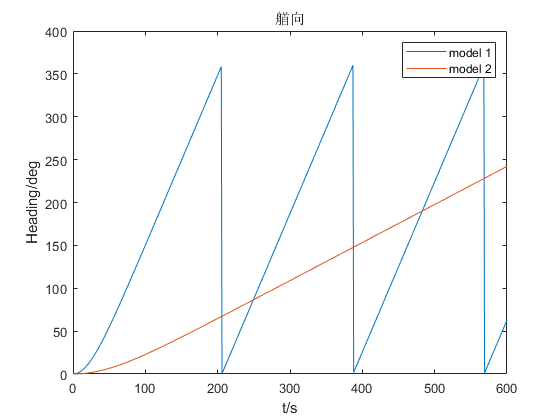


figure
plot(t_data, x1_data(:, 3)*to_deg, t_data, x2_data(:, 3)*to_deg);
title("艏向");xlabel("t/s");ylabel("Heading/deg")
legend("model 1", "model 2");

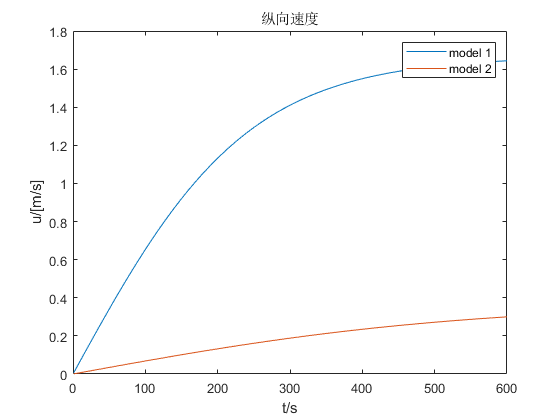


figure
plot(t_data, x1_data(:, 4), t_data, x2_data(:, 4));
title("纵向速度");xlabel("t/s");ylabel("u/[m/s]")
legend("model 1", "model 2");

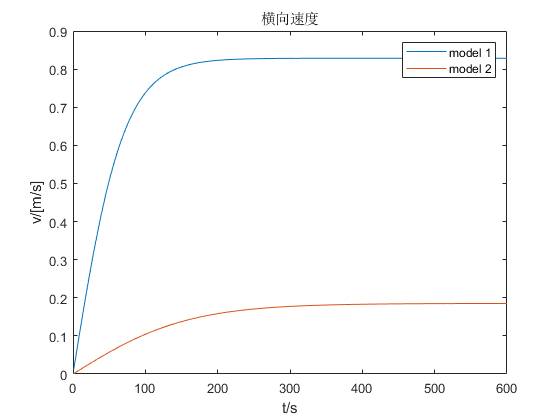


figure
plot(t_data, x1_data(:, 5), t_data, x2_data(:, 5));
title("横向速度");xlabel("t/s");ylabel("v/[m/s]")
legend("model 1", "model 2");

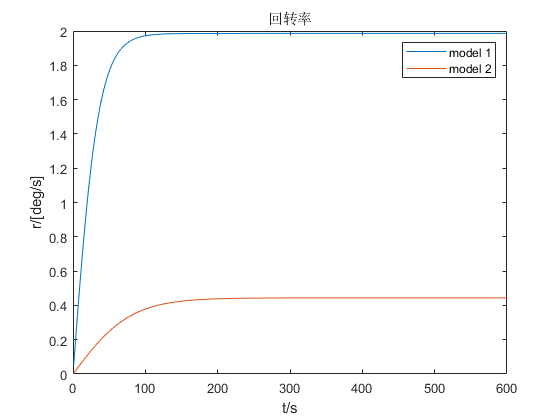


figure
plot(t_data, x1_data(:, 6)*to_deg, t_data, x2_data(:, 6)*to_deg);
title("回转率");xlabel("t/s");ylabel("r/[deg/s]")
legend("model 1", "model 2");